# Quanser QUBE-Servo 2 Inverted Pendulum Balance Control using Reinforcement Learning

This example shows how to design a reinforcement learning agent using the [MathWorks Reinforcement Learning Toolbox ](https://www.mathworks.com/products/reinforcement-learning.html)to balance the Quanser [QUBE-Servo 2](https://www.quanser.com/products/qube-servo-2/) Inverted Pendulum system, shown below. 

This system has two encoders to measure the position of the rotary arm (i.e., the DC motor angle) and the pendulum link and a DC motor at the base of the rotary arm. 

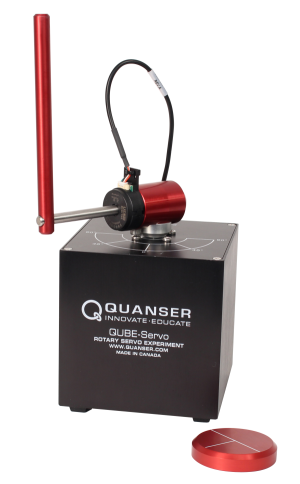

## How Does it Work?

The Reinforcement Learning (RL) design is discussed in this Quanser [blog](https://www.quanser.com/blog/using-the-reinforcement-learning-toolbox-to-balance-an-inverted-pendulum/) and includes videos showing the system in action. We also have an eBook version that contains more detail. The agent is trained using the following Simulink model.

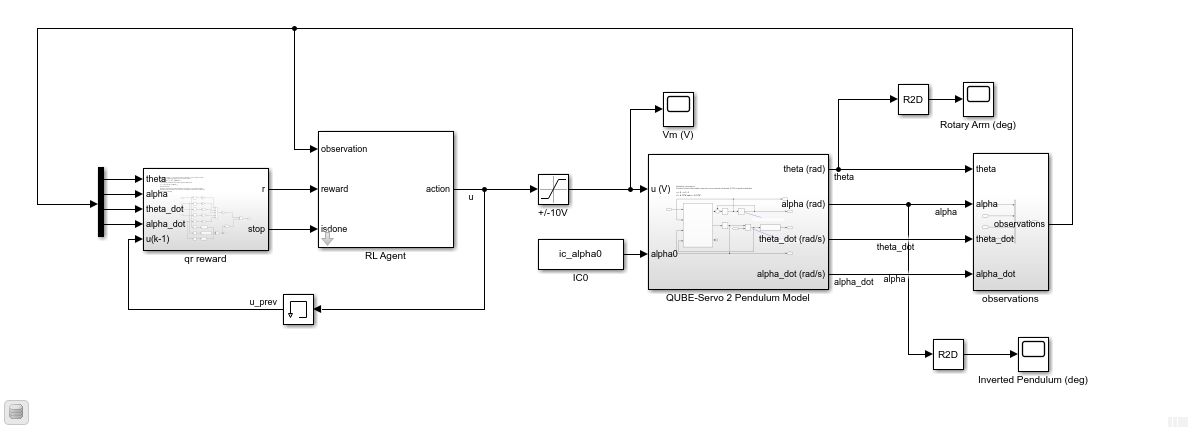

The Simulink model uses a nonlinear model of the QUBE-Servo 2 as the RL *environment *and the RL Agent block to implement the agent. The agent uses the *observation *and *reward *signals and outputs an *action*, i.e., motor voltage, to balance the pendulum. 

## Before You Run this Example

The pendulum RL balance control can be run using the virtual twin of the QUBE-Servo 2, or the actual hardware. Here are the requirements:

- MathWorks [Reinforcement Learning Toolbox](https://www.mathworks.com/products/reinforcement-learning.html). The *RL Agent *block is used to train a new agent or load an existing one.

- Quanser [QLabs Virtual QUBE-Servo 2](https://www.quanser.com/products/qlabs-virtual-qube-servo-2/) software. Only needed to run the agent using the QUBE-Servo 2 Virtual Twin. If you don't have QLabs, you can sign up for a free trial [here](https://www.quanser.com/products/qlabs-virtual-qube-servo-2/).

- Quanser [QUARC Real-Time Control Software](https://www.quanser.com/products/quarc-real-time-control-software/) and the MathWorks [Deep Learning Toolbox](https://www.mathworks.com/products/deep-learning.html) are required to run the agent using the QUBE-Servo 2 hardware. If you don’t have the QUARC software, you can sign up for [free trial](https://www.quanser.com/products/quarc-real-time-control-software/).

## How to Run the Example

- Select whether you want to load a previously trained agent or train a new one from the drop down box below. It is recommended that you start by testing the existing agent first.

- Run each section of the script in sequence up until the Simulate the QUBE-Servo 2 IP RL section.

- Simulate the RL balance control on the Simulink model shown above as described in that section (e.g., change the initial vertical angle).

- Go to the Running RL using the Virtual QUBE-Servo 2 IP Experiment section if you want to run the RL balance control agent using the QUBE-Servo 2 virtual twin.

- Go to the Running RL using the QUBE-Servo 2 IP Hardware section if you want to run RL balance control using the QUBE-Servo 2 hardware.

% Load pre-defined agent (false) or train new agent (true)
doTraining = false;

## Setup Environment

The environment includes the plant, any disturbances, the observation signals and action signals, and anything else that is outside the agent. 

% load QUBE-Servo 2 Pendulum parameters
run("qube2_rotpen_param.m");
% initial pendulum angle (rad)
ic_alpha0 = pi; % set to pi to start pendulum in inverted position, 0 for down position
% Maximum voltage (V)
Vmax = 5;
% max rotary arm angle +/- 60 deg
theta_max = 60*pi/180;
% inverted pendulum angle balance threshold (rad)
alpha_bal_threshold = 10*pi/180;
% reward QR weights
q11 = 10; q22 = 20; q33 = 0; q44 = 1; r = 0.1; B = -100; % agent 9

### Observation and Action Signals

Define the observation and action signals of the environment based on the QUBE-Servo 2 system and setup the interface to the Simulink model / environment that contains the nonlinear model of the pendulum. For the rotary inverted pendulum there are four observation signals - the angular position and velocity of the rotary arm and the pendulum link, i.e., $[\theta,\alpha,\dot{\theta},\dot{\alpha}]$,and one action signal - the motor voltage, $V_m
$. The reset function that changes the initial position of the inverted pendulum about the vertical between +/- 10 deg is also defined.

% observation signals "rlNumericSpec" creates action/observative data of a given dimension and signal limits
obsInfo = rlNumericSpec([4 1],'LowerLimit',[-inf -inf -inf -inf]','UpperLimit',[inf inf inf inf]');
obsInfo.Name = 'observations';
obsInfo.Description = 'theta, alpha, theta_dot, alpha_dot';
numObs = obsInfo.Dimension(1);
% action signals - constrained to motor limit
actInfo = rlNumericSpec([1 1],'LowerLimit',-Vmax,'UpperLimit',Vmax);
actInfo.Name = 'Motor Voltage';
% numActions = actInfo.Dimension(1);
% create environment object
mdl = 's_qube2_bal_rl';
agentBlk = [mdl '/RL Agent'];
env = rlSimulinkEnv(mdl,agentBlk,obsInfo,actInfo);

% reset function used to randomize initial position of pendulum
env.ResetFcn = @(in)localResetFcn(in);
% Sampling rate
Ts = 0.01;
% Simulation duration
Tf = 2;
% Fix the random generator seed for reproducibility.
rng(0);

## Create DDPG Agent

The MathWorks® Reinforcement Learning Toolbox™ includes several different types of agents that can be used to generate a policy. The deep deterministic policy gradient (DDPG) algorithm is a model-free, online, off-policy reinforcement learning method. DDPG agent is an actor-critic RL agent that finds an optimal policy to maximizes the long-term reward. 

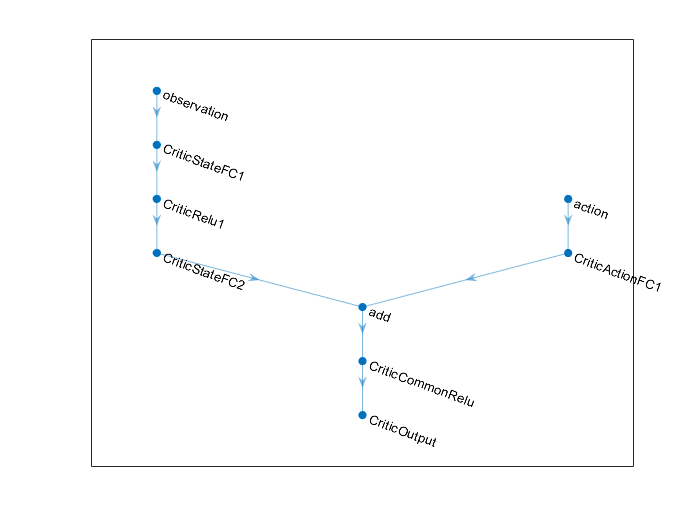

statePath = [
    imageInputLayer([numObs 1 1],'Normalization','none','Name','observation')
    fullyConnectedLayer(128,'Name','CriticStateFC1')
    reluLayer('Name', 'CriticRelu1')
    fullyConnectedLayer(200,'Name','CriticStateFC2')];
actionPath = [
    imageInputLayer([1 1 1],'Normalization','none','Name','action')
    fullyConnectedLayer(200,'Name','CriticActionFC1','BiasLearnRateFactor',0)];
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','CriticOutput')];
% 
criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
%  
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');
% plot network
plot(criticNetwork)

% 
% Specify options for the critic representation .
criticOpts = rlRepresentationOptions('LearnRate',1e-3,'GradientThreshold',1);
% 
% Create critic representation using the specified deep neural network 
obsInfo = getObservationInfo(env);
actInfo = getActionInfo(env);
critic = rlQValueRepresentation(criticNetwork,obsInfo,actInfo,'Observation',{'observation'},'Action',{'action'},criticOpts);
% 
% Create the actor, first create a deep neural network with one input, 
% the observation, and one output, the action.
% Construct actor similarly to the critic. 
actorNetwork = [
    imageInputLayer([numObs 1 1],'Normalization','none','Name','observation')
    fullyConnectedLayer(128,'Name','ActorFC1')
    reluLayer('Name','ActorRelu1')
    fullyConnectedLayer(200,'Name','ActorFC2')
    reluLayer('Name','ActorRelu2')
    fullyConnectedLayer(1,'Name','ActorFC3')
    tanhLayer('Name','ActorTanh')
    scalingLayer('Name','ActorScaling','Scale',max(actInfo.UpperLimit))];
% 
actorOpts = rlRepresentationOptions('LearnRate',5e-04,'GradientThreshold',1);
% 
actor = rlDeterministicActorRepresentation(actorNetwork,obsInfo,actInfo,'Observation',{'observation'},'Action',{'ActorScaling'},actorOpts);
% specify agent options
agentOpts = rlDDPGAgentOptions(...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'ExperienceBufferLength',1e6,...
    'DiscountFactor',0.99,...
    'MiniBatchSize',128);
% For continuous action signals, it is important to set the noise variance 
% appropriately to encourage exploration. It is common to have 
% Variance*sqrt(Ts) be between 1% and 10% of your action range
agentOpts.NoiseOptions.Variance = 0.4; 
agentOpts.NoiseOptions.VarianceDecayRate = 1e-5;
% 
% create the DDPG agent using the specified actor representation, critic 
% representation and agent options.
agent = rlDDPGAgent(actor,critic,agentOpts);

## Train/Load Agent

Sets up the parameters and launches the reinforcement learning training session to create a new agent or load a previously trained agent. You can select what agent MAT file to load and what the MAT file name to use when creating a new agent. 

% Maximum # of steps for training
maxsteps = ceil(Tf/Ts);
% Setup up training parametesr
trainOpts = rlTrainingOptions(...
    'MaxEpisodes',1000, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'ScoreAveragingWindowLength',5, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',-10);
% 
if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
    % Save trained agent
    save('QubeIPBalDDPG10.mat','agent');
else
    % Load pretrained agent.
    load('QubeIPBalDDPG09.mat','agent');
    % load('QubeIPBalDDPGNominalParam.mat','agent');
end

## Simulate RL using the QUBE-Servo 2 Inverted Pendulum Model

This Simulink model that was used in the training can be used to simulate the pendulum balance RL control using the nonlinear rotary pendulum model.

- Open the s_qube2_bal_rl Simulink model, as shown below.

- Run the Simulink model. 

- Try changing in the initial angle of the inverted pendulum somewhere between +/- 10 deg.  For example, set the *IC0* block to *0.96*ic_alpha0* to have the initial angle start at 172.8 deg, which is 7.2 deg away from the inverted position. Note: The *ic_alpha0 *variable is initially set to $\pi$ or 180 deg, i.e., the angle of the inverted pendulum when balanced and perfectly upright.

% open Simulink model to simulate QUBE-Servo 2 RL balance control
open("s_qube2_bal_rl.slx");

The response of the rotary arm and pendulum when the pendulm starts at approximately -7.5 deg from the upright balance position is shown in the *Rotary Arm (deg) *and *Inverted Pendulum (deg)* scopes below. The voltage applied to the motor is shown in the *Vm (V)* scope. 

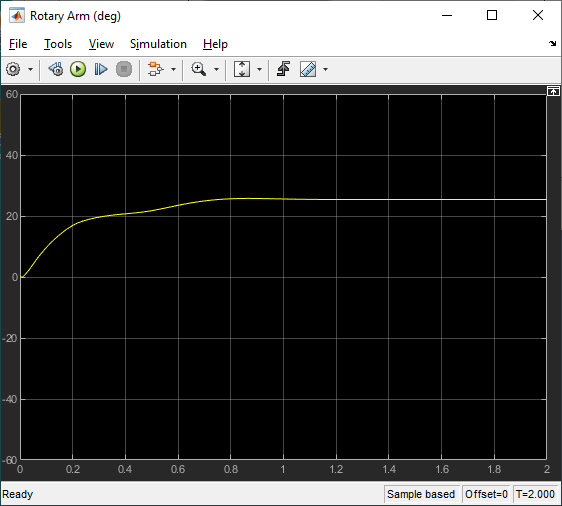 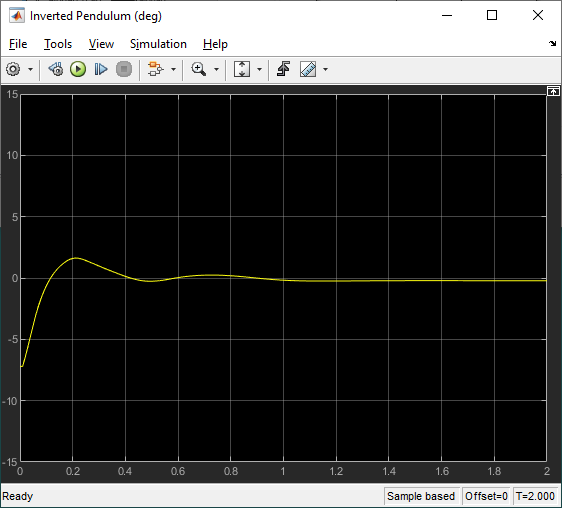 

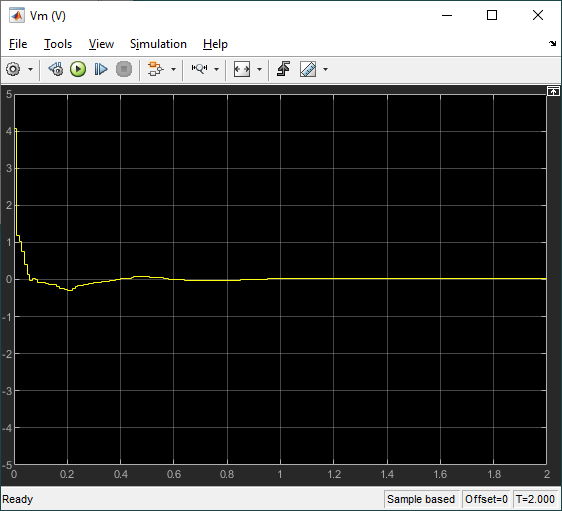

## Running RL using the Virtual QUBE-Servo 2 IP Experiment

Run the reinforcement learning agent using the [QLabs Virtual QUBE-Servo 2](https://www.quanser.com/products/qlabs-virtual-qube-servo-2/) Experiment through Simulink. If you don't have QLabs and want to try it out, you can request for a free trial [here](https://www.quanser.com/products/qlabs-virtual-qube-servo-2/).

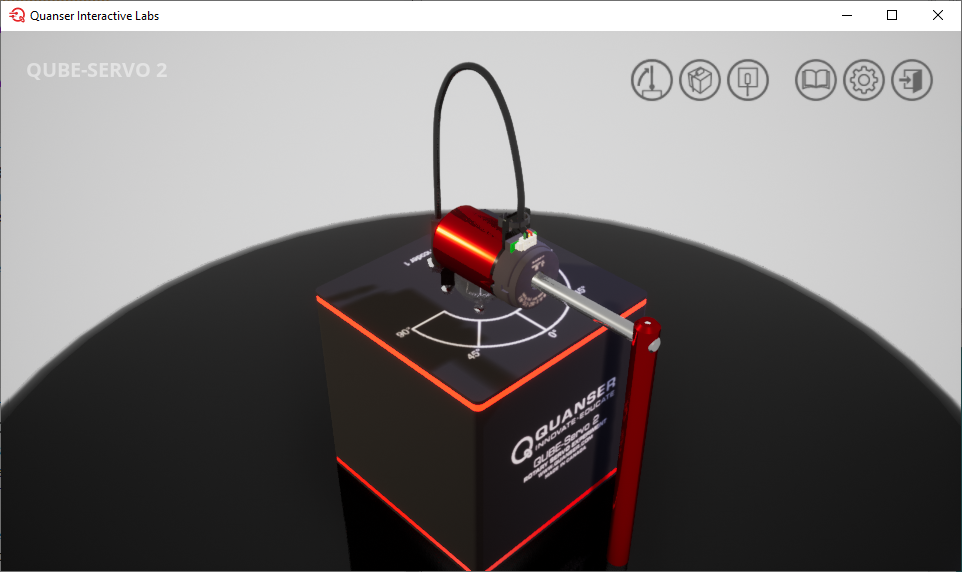

- Open the Quanser Interactive Labs (QLabs) software and make sure the *Pendulum* *Workspace *in the *QUBE 2 - Pendulum *menu is loaded as shown above. If you have any issues running the software, please go to the [QLabs support page](https://portal.quanser.com/Support). 

- Open the Simulink model that interacts with the Virtual QUBE-Servo 2 Pendulum, as shown below.

- Run the Simulink model. 

- Click on the "Lift pendulum" button in the top-right corner to bring the pendulum up to the inverted position. The RL balance control will engage once the pendulum reaches +/- 10 deg of the vertical.

% open Simulink model to run RL balance control using the Virtual QUBE-Servo 2 pendulum
open("qlabs_qube2_bal_rl.slx");

The scopes below show the response when the system is in steady-state balance mode in the virtual QUBE-Servo 2. 

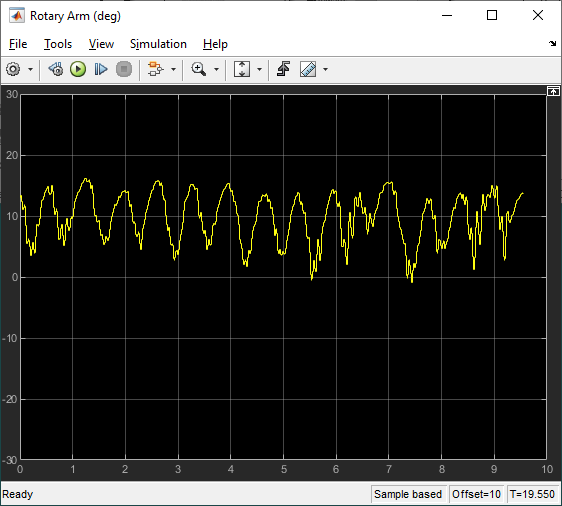 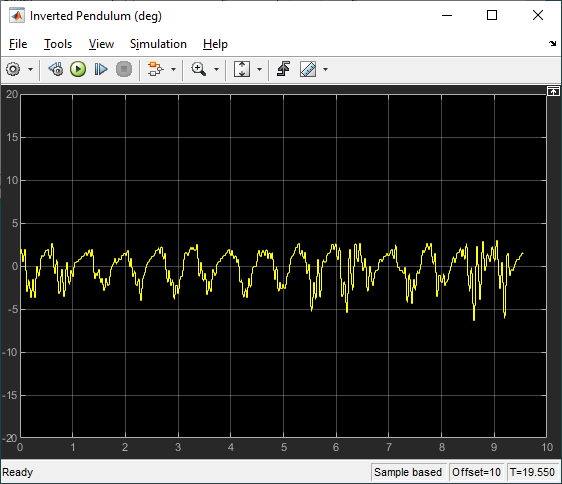

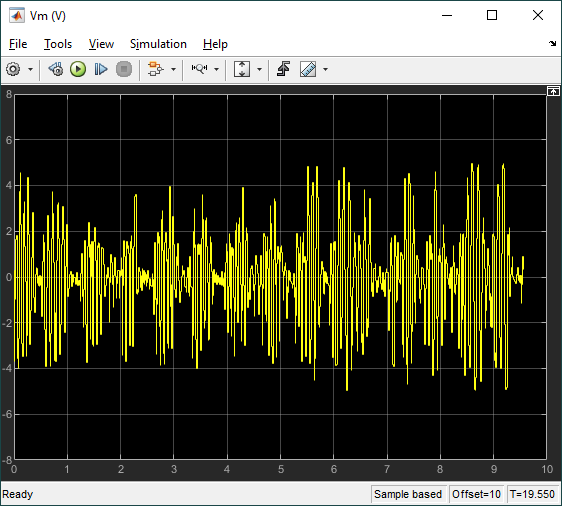

## Running RL using the QUBE-Servo 2 IP Hardware

The [Quanser QUARC Real-Time Control Software](https://www.quanser.com/products_category/software/) is needed to interface to the QUBE-Servo 2 hardware through Simulink. QUARC creates an executable for 64-bit Windows using code generation from Simulink Coder and MATLAB Code. The QUARC executable is then run through the Simulink interface in full *External* mode. Currently in R2021a, the *RL Agent* block does not support code generation. Instead, the trained agent is deployed on the 64-bit Windows target with QUARC using the *Predict *block from the Deep Learning Toolbox, as shown below. 

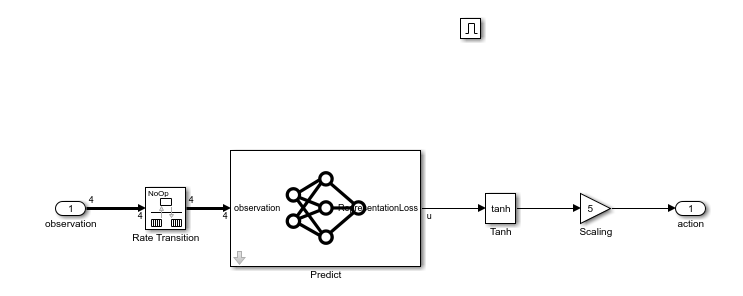

### Generate Policy

Generate the policy of the trained agent for the Deep Learning *Predict *block or load a previously created one.

% Load pre-defined policy (false) or generate new policy for RT code gen (true)
doPolicy = false;
% doPolicy = true;
% 
if doPolicy
    % Generate policy for deployment
    generatePolicyFunction(agent,'MATFileName','QubeIPBalRLPolicy.mat');
    load("QubeIPBalRLPolicy.mat");
    policy = cut_unnecessary_layers_for_SAC_policy(policy);
    save("QubeIPBalRLPolicy.mat", 'policy');
else
    % Load previously saved policy
    load("QubeIPBalRLPolicy.mat");
end

### Run Simulink/QUARC

Instructions on how to use Simulink and the QUARC Real-Time Control Software to run the RL balance control using the QUBE-Servo 2 hardware.

- Connect the QUBE-Servo 2 to the PC/laptop USB port.

- Make sure the QUBE-Servo 2 is powered and Power LED is lit.

- Open the Simulink model that interacts with the QUBE-Servo 2 given below. 

- Click on the "Monitor and Tune" button in the Simulink toolbar to generate and run the QUARC controller. 

- Once the LED is green, manually bring up the pendulum to the vertical position. Immediately release the pendulum once the controller engages (i.e., when it's within +/- 10 deg of vertical).

- Click on the Stop button to stop running the QUARC controller.

% load the Simulink model that uses QUARC to run the RL balance control using the QUBE-Servo 2
open("q_qube2_bal_rl_hw.slx");

The sample response when the RL policy is deployed and run by QUARC are shown in the scopes below. Here we see an improvement over the Virtual Twin responses. The rotary arm oscillations are smaller, and the pendulum moves less, as it balances about the vertical position. The motor command signal is also smaller, but still has some high-frequency components.  

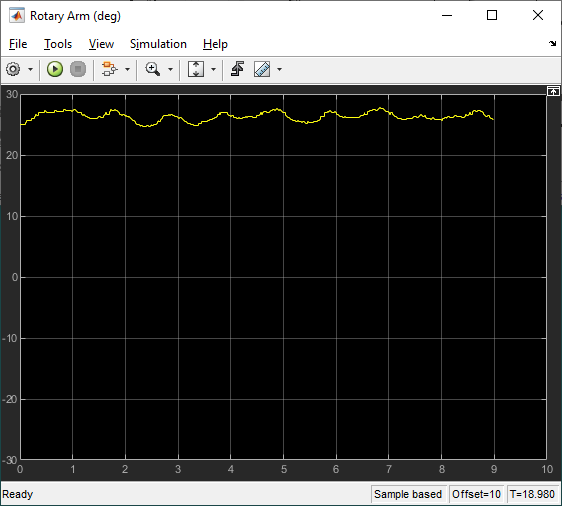 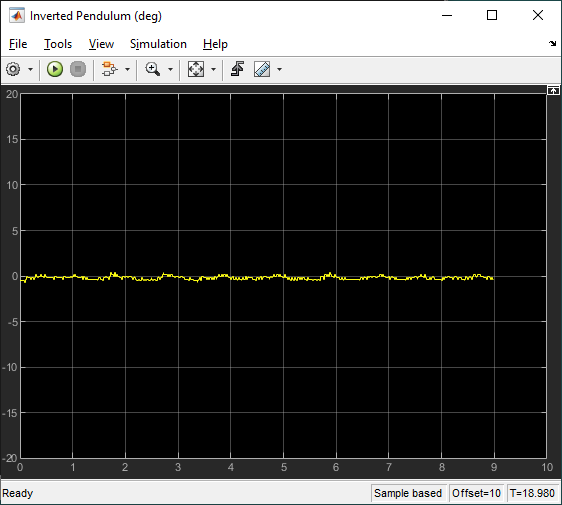

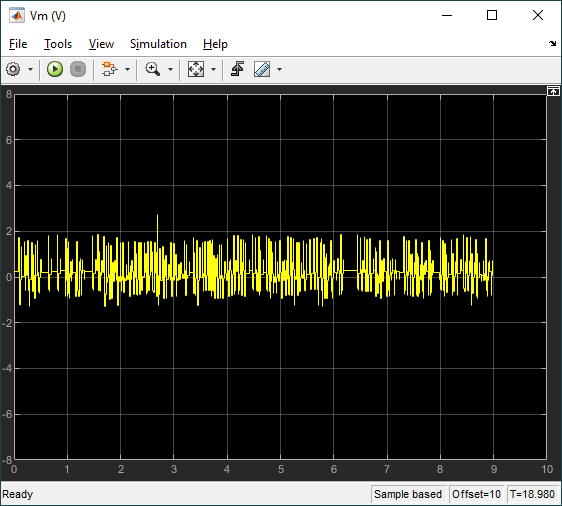

## Resources

- Using the Reinforcement Learning Toolbox™ to Balance an Inverted Pendulum Quanser blog: [https://www.quanser.com/blog/using-the-reinforcement-learning-toolbox-to-balance-an-inverted-pendulum/](https://www.quanser.com/blog/using-the-reinforcement-learning-toolbox-to-balance-an-inverted-pendulum/)

- MathWorks® Reinforcement Learning eBook: [https://www.mathworks.com/campaigns/offers/reinforcement-learning-with-matlab-ebook.html](https://www.mathworks.com/campaigns/offers/reinforcement-learning-with-matlab-ebook.html)

- Reinforcement Learning Tech Talks videos by Brian Douglas: [https://www.mathworks.com/videos/series/reinforcement-learning.html](https://www.mathworks.com/videos/series/reinforcement-learning.html)

- MathWorks® Reinforcement Learning Toolbox™ product page: [https://www.mathworks.com/products/reinforcement-learning.html](https://www.mathworks.com/products/reinforcement-learning.html)

- Reinforcement Learning: training and deploying a policy to control inverted pendulum with QUBE-Servo 2: [https://www.mathworks.com/matlabcentral/fileexchange/99364-reinforcement-learning-inverted-pendulum-with-qube-servo2?s_tid=srchtitle](https://www.mathworks.com/matlabcentral/fileexchange/99364-reinforcement-learning-inverted-pendulum-with-qube-servo2?s_tid=srchtitle). Shows how to implement a swing-up and balance RL routine on the QUBE-Servo 2 system using a Raspberry Pi embedded target. 

## Reset Function

The reset function sets the initial angle of the inverted pendulum between +/- 10 deg of the vertical at the start of each training episode. 

function in = localResetFcn(in)
    % randomize initial inverted position angle
    blk = sprintf('s_qube2_bal_rl/IC0');
    % initialize angle of pendulum +/- 10 deg about vertical upright position
    ic0 = ( 20 * ( rand()-0.5) + 180 ) * pi/180;
    in = setBlockParameter(in,blk,'Value',num2str(ic0));
end